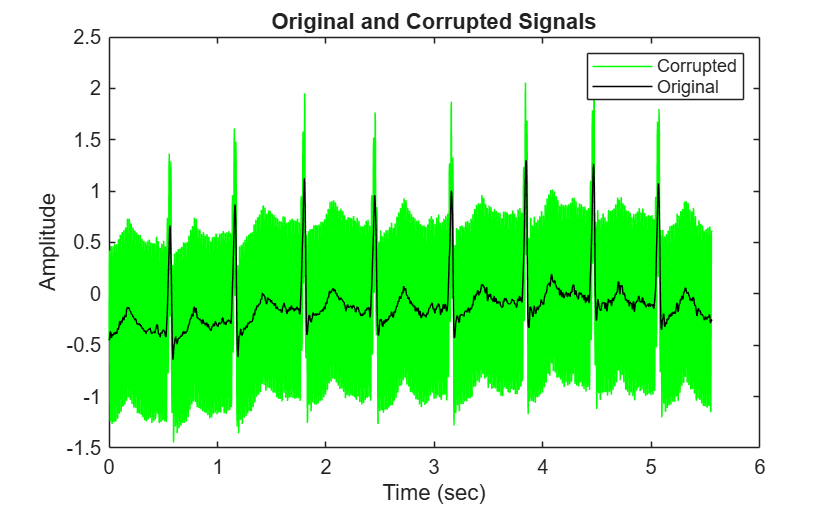

% Assignment 5
% Step 1.
clear % Clear variables
close all % Close all opened figures
load signal.mat % Load the ECG signal
Fs = 360; % Sampling frequency of the ECG signal
f0 = 60; % Frequency of the noise
N = length(signal); % Length of the signal
t = (0:(N-1))/Fs; % Define the time variable
noise = sin(2*pi*f0*t); % Create a nose signal (line noise)
noisy_signal = signal + noise; % Create a noisy signal
% Display the signals
plot(t, noisy_signal, 'g', t, signal, 'k')
xlabel('Time (sec)')
ylabel('Amplitude')
title('Original and Corrupted Signals')
legend('Corrupted', 'Original')




%step 2: plot fft
signal_z = fftshift(fft(signal));
noisy_signal_z = fftshift(fft(noisy_signal));

k = (-N/2:N/2-1);
frequency = k*Fs/N

frequency =  -180.0000 -179.8201 -179.6402 -179.4603 -179.2804 -179.1004 -178.9205 -178.7406 -178.5607 -178.3808 -178.2009 -178.0210 -177.8411 -177.6612 -177.4813 -177.3013 -177.1214 -176.9415 -176.7616 -176.5817 -176.4018 -176.2219 -176.0420 -175.8621 -175.6822 -175.5022 -175.3223 -175.1424 -174.9625 -174.7826 -174.6027 -174.4228 -174.2429 -174.0630 -173.8831 -173.7031 -173.5232 -173.3433 -173.1634 -172.9835 -172.8036 -172.6237 -172.4438 -172.2639 -172.0840 -171.9040 -171.7241 -171.5442 -171.3643 -171.1844


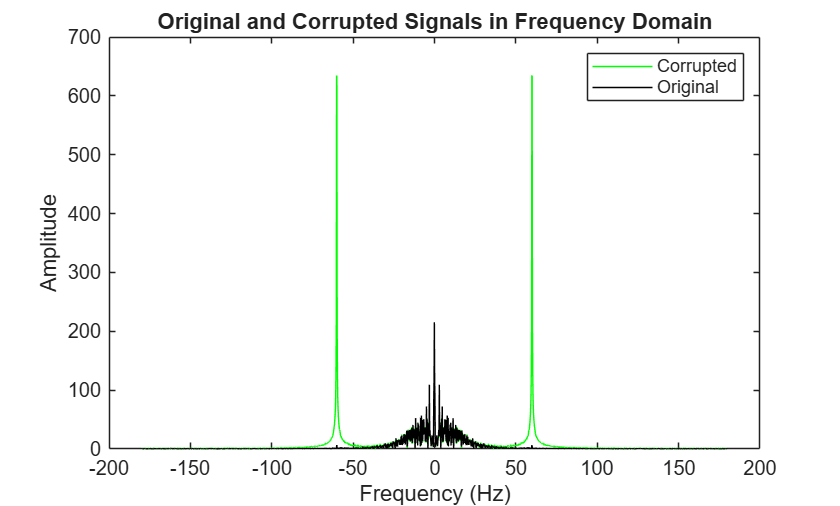


plot(frequency, abs(noisy_signal_z), 'g', frequency, abs(signal_z), 'k')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('Original and Corrupted Signals in Frequency Domain')
legend('Corrupted', 'Original')
hold off;


%step 3: find peaks, confirm it's at 60Hz
[peak_value, peak_sample] = findpeaks(abs(noisy_signal_z),'NPeaks',2,SortStr="descend");
peak_value

peak_value =   634.5659  634.5659


peak_freq = frequency(peak_sample)

peak_freq =   -60.1799   60.0000


**Step 4: filter design**

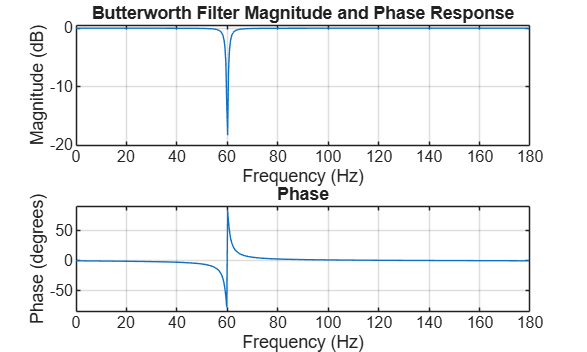

%butterworth filter
[b_bw, a_bw] = butter(1,[59,61]/(Fs/2),"stop");
freqz(b_bw,a_bw,[],Fs)
title('Butterworth Filter Magnitude and Phase Response')

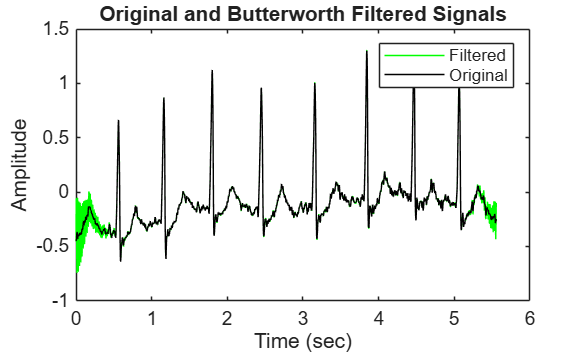


%filter the signal noise
signal_bw_filtered = filtfilt(b_bw,a_bw,noisy_signal);
% Display the signals
plot(t, signal_bw_filtered,'g', t, signal,'k')
xlabel('Time (sec)')
ylabel('Amplitude')
title('Original and Butterworth Filtered Signals')
legend('Filtered', 'Original')

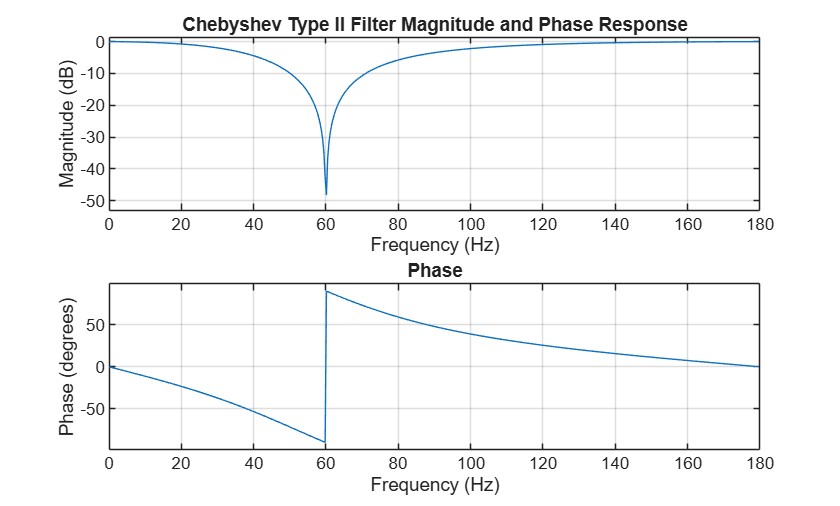

%Chebyshev Type II filter
[b_cheby, a_cheby] = cheby2(1, 30, [59, 61]/(Fs/2), 'stop');
freqz(b_cheby, a_cheby, [], Fs)
title('Chebyshev Type II Filter Magnitude and Phase Response')

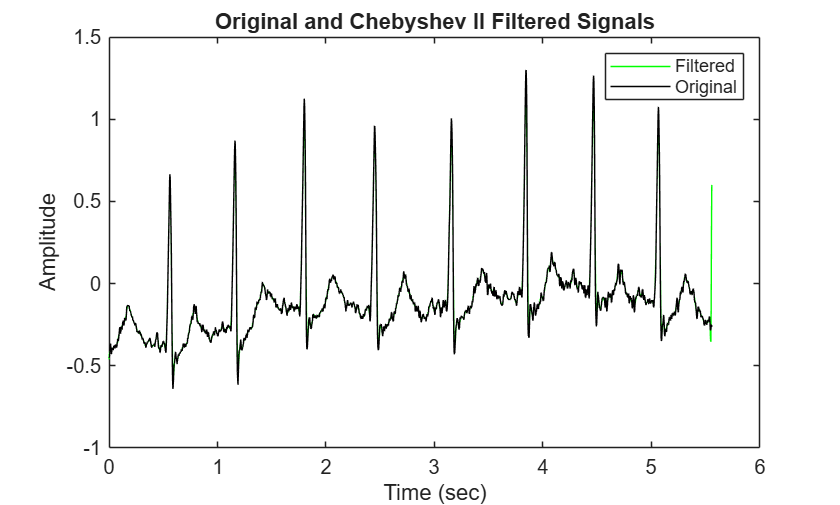


%filter the signal noise
signal_chebyII_filtered = filtfilt(b_cheby,a_cheby,noisy_signal);
% Display the signals
plot(t, signal_chebyII_filtered,'g', t, signal,'k')
xlabel('Time (sec)')
ylabel('Amplitude')
title('Original and Chebyshev II Filtered Signals')
legend('Filtered', 'Original')

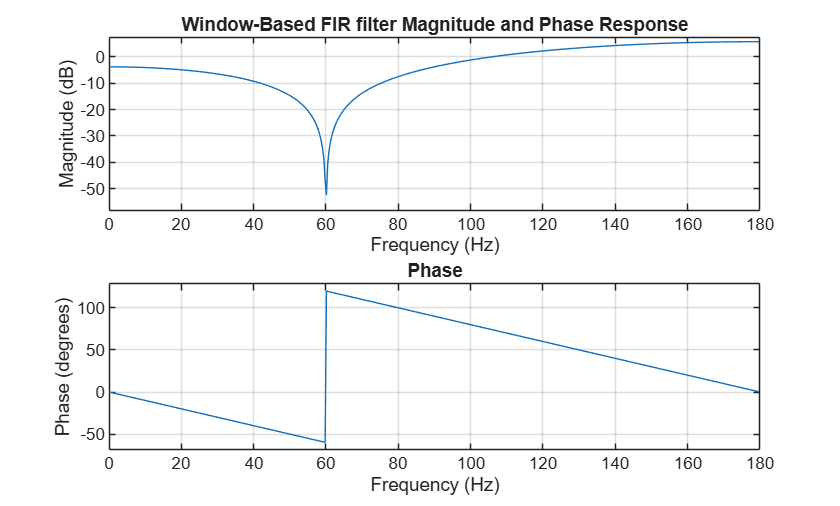

%Window-based FIR filter
% Define the window length and the desired cutoff frequency
b_window = fir1(400,[59,61]/(Fs/2),"stop");
freqz(b_cheby,1,[],Fs)
title("Window-Based FIR filter Magnitude and Phase Response")

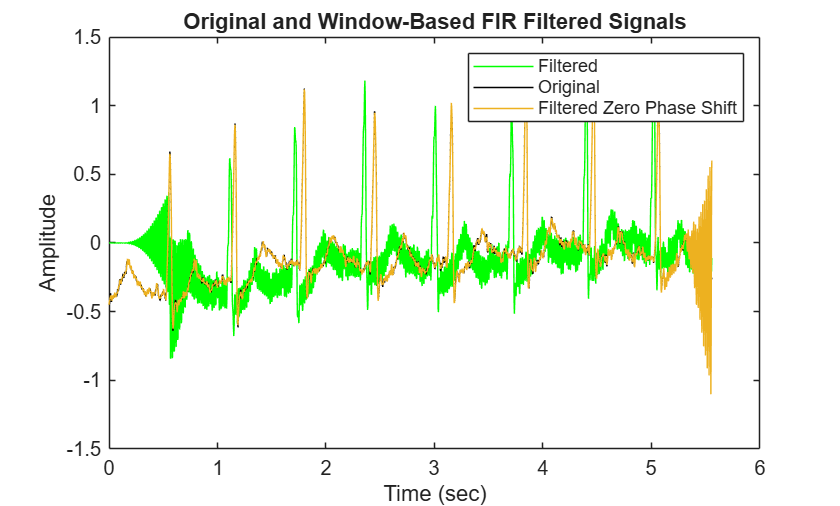


%filter the signal noise 
signal_windowFIR_filtered = filter(b_window,1,noisy_signal);
signal_windowFIR_filtered_zerophase = filtfilt(b_window,1,noisy_signal);
%Display signals
plot(t, signal_windowFIR_filtered,'g', t, signal,'k', t,signal_windowFIR_filtered_zerophase)
xlabel('Time (sec)')
ylabel('Amplitude')
title('Original and Window-Based FIR Filtered Signals')
legend('Filtered', 'Original', 'Filtered Zero Phase Shift')

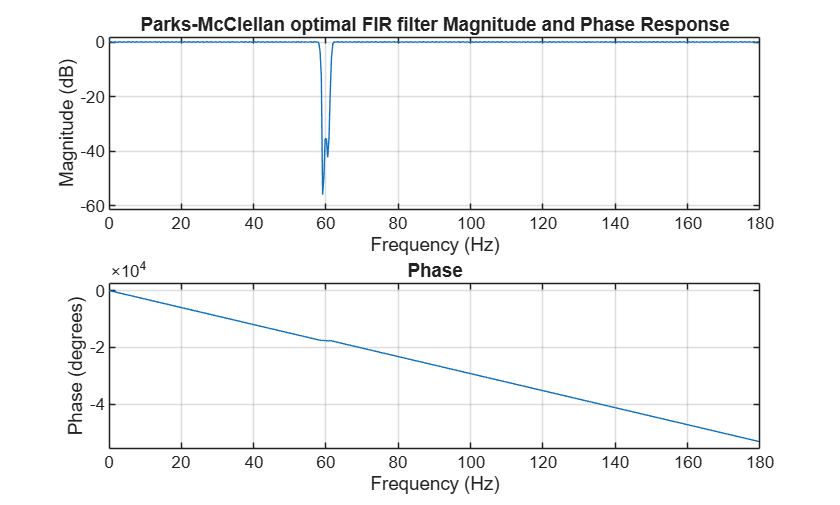

%Parks-McClellan optimal FIR filter
b_parks = firpm(600,[0,58,59,61,62,Fs/2]/(Fs/2),[1,1,0,0,1,1]);
freqz(b_parks,1,[],Fs)
title("Parks-McClellan optimal FIR filter Magnitude and Phase Response")

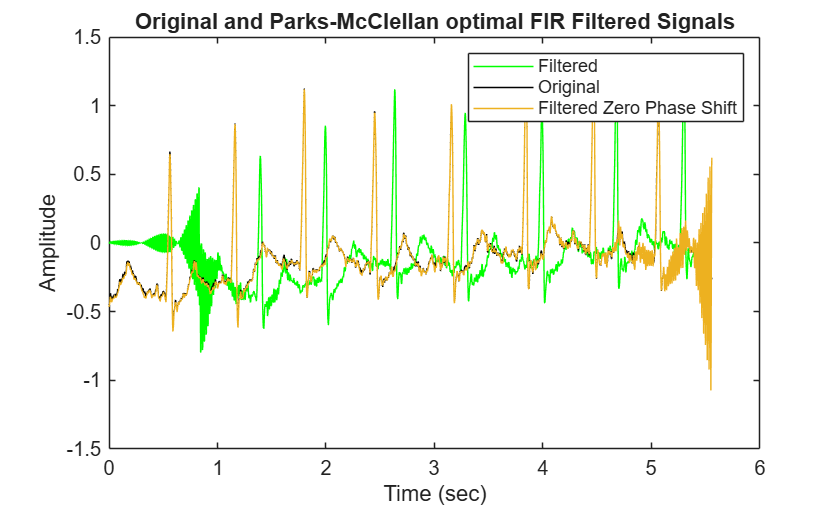


%filter the signal noise 
signal_parks_filtered = filter(b_parks,1,noisy_signal);
signal_parks_filtered_zerophase = filtfilt(b_parks,1,noisy_signal);
%display signal
plot(t, signal_parks_filtered,'g', t, signal,'k', t,signal_parks_filtered_zerophase)
xlabel('Time (sec)')
ylabel('Amplitude')
title('Original and Parks-McClellan optimal FIR Filtered Signals')
legend('Filtered', 'Original', 'Filtered Zero Phase Shift')

**Step 5:**

In regards to the ECG signals, the butterworth filter seems to more or less follow the original signal, but has issues with noise at the start and end of the signal. The Chebysev filtered signal also follows the original signal well without the issues of noise at the start and end, but it has issues with spiking in value at the end. The window-based FIR signal has issues of shifting in time and having large amounts of noise at the first pules, while its filtered zero phase shift equivalent can remove most of the noise and follow the original signal well, there are large issues with noise at the end. The same applies to the Parks-McClellan optimal FIR filtered signal, but the issues with noise on the filtered signal with no zero phase shift is slightly less noticeable on the first pulse of the ECG signal.

In the context of a ECG signal that is monitoring a heartbeat, the Chebysev II filter's noise at the end spiking artificially creates another "pulse" in the signal, so it should not be used. both FIR filters have the first pulse with lots of noise and is shifted in time, while their zero phase shift filtered versions have noise spike so much at the end, it may be seen as possibly another pulse. 

Therefore, I would reccomend using the butterworth filter for this purpose.